# Using a random forest regressor to estimate central BP from age, heart rate, and cuff BP

This function trains two random forest regression models to estimate respectively central systolic (CSBP) and diastolic blood pressure (CDBP) from age, heart rate (HR), and (cuff) brachial systolic (BSBP) and diastolic BP (BDBP). It uses data from the publicly available [Pulse Wave Database](https://peterhcharlton.github.io/pwdb/), which consists of simulated haemodynamic data (described in [this article](https://doi.org/10.1152/ajpheart.00218.2019), and available for download [here](https://doi.org/10.5281/zenodo.3275625)). This dataset contains simulated haemodynamic and pulse wave data for virtual subjects aged from 25 to 75 (in 10-year increments).

**Step 1: Load the data**

Load the PWDB data set (described in [this article](https://doi.org/10.1152/ajpheart.00218.2019), and available [here](https://doi.org/10.5281/zenodo.2633174) - the `pwdb_data.mat` file is required to run this case study).

% specify the path of the data file
up.paths.pwdb_data_file = '/pathname/pwdb_data.mat';

% load the data (if it hasn't already been loaded)
if ~exist('data','var')
    if ~exist(up.paths.pwdb_data_file, 'file'), error('Couldn''t locate the ''pwdb_data.mat'' file.'), end
    load(up.paths.pwdb_data_file);
end

**Step 2: Extract the required parameters**

Extract relevant data from the `data` variable.

% identify subjects with physiologically plausible data
rel_subjs = data.plausibility.plausibility_log;     % select only those subjects with physiologically plausible haemdodynamics

% extract BSBP, BDBP, CSBP, and CDBP for these subjects
age = data.pw_inds.age(rel_subjs);
hr = extractfield(data.haemods, 'HR');         % extract the heart rate
hr = hr(rel_subjs); hr = hr(:);

bsbp = data.pw_inds.Brachial_SBP_V(rel_subjs);
bdbp = data.pw_inds.Brachial_DBP(rel_subjs);
csbp = data.pw_inds.AorticRoot_SBP_V(rel_subjs);
cdbp = data.pw_inds.AorticRoot_DBP(rel_subjs);

% seperate inputs and outputs
X = [age, hr, bsbp, bdbp];
y = [csbp, cdbp];

The variables contain values for age, hr, BSBP, BDBP, CSBP, and CDBP from the 3,837 virtual (i.e. simulated) subjects with physiologically plausible haemodynamics.

**Step 3: Split into training, validation, and testing data **

The 60 % of the data was used for the training,  20 % for testing the regression model, and the remaining 20 % was used for the external validation. The split into the three sets was done in a random manner.

rows = length(find(rel_subjs));
train_split = 0.6;  %  select the training set size (as % of the entire dataset)
idx = randperm(rows); split_index = round(train_split*rows);

X_train = X(idx(1:split_index),:);
y_train = y(idx(1:split_index),:);
X_test_val = X(idx(split_index+1:end),:);
y_test_val = y(idx(split_index+1:end),:);

rows = length(y_test_val);
test_split = 0.5;  %  select the training set size (as % of the subset)
idx = randperm(rows); split_index = round(test_split*rows);

X_test = X_test_val(idx(1:split_index),:);
y_test = y_test_val(idx(1:split_index),:);
X_val = X_test_val(idx(split_index+1:end),:);
y_val = y_test_val(idx(split_index+1:end),:);

y_train_csbp = y_train(:,1); y_train_cdbp = y_train(:,2);
y_test_csbp = y_test(:,1); y_test_cdbp = y_test(:,2);
y_val_csbp = y_val(:,1); y_val_cdbp = y_val(:,2);

fprintf('Training data: %d subjects\n', length(y_train_csbp));

Training data: 2302 subjects


fprintf('Testing data: %d subjects\n', length(y_test_csbp));

Testing data: 768 subjects


fprintf('Validation data: %d subjects\n', length(y_val_csbp));

Validation data: 767 subjects


**Step 4: Train the two random forest regressors**

Train two random forest regressors using age, hr, BSBP and BDBP as predictor variables (inputs), and CSBP and CDBP as the two response variables (outputs), respectively. 

% train models
num_trees = 100;     % number of regression trees
func_csbp = TreeBagger(num_trees,X_train, y_train_csbp,'Method','regression'); 
func_cdbp = TreeBagger(num_trees,X_train, y_train_cdbp,'Method','regression'); 

**Step 5: Visualize the regression trees**

tree_index = 1;  % select a tree
% view(func_csbp.Trees{tree_index},'mode','graph') % graphic description
% view(func_cdbp.Trees{tree_index},'mode','graph') % graphic description

**Step 6: Compare the model estimates to the true CSBP and CDBP values**

Use the models to calculate estimates of CSBP/CDBP from age, hr, BSBP and BDBP:

% calculate model estimates for CSBP (using Matlab function)
y_pred_csbp = predict(func_csbp, X_test);
% calculate model estimates for CDBP (using Matlab function)
y_pred_cdbp = predict(func_cdbp, X_test);

Plot the results as scatter plot of estimated against reference CSBP, and Bland-Altman plot showing the limits of agreement (LOAs) between the estimated and reference CSBP.

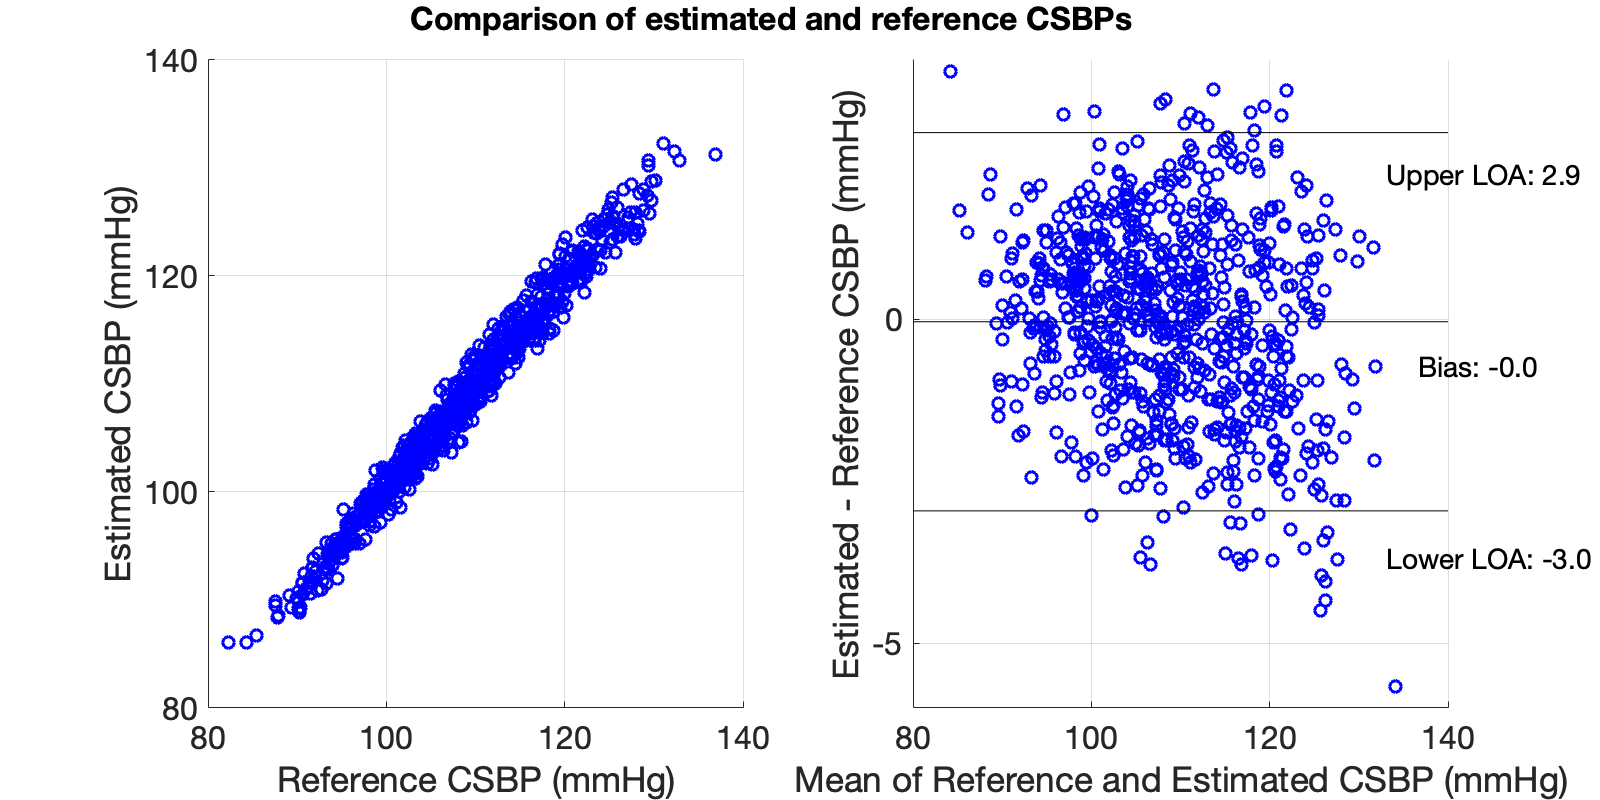

% plot options
figure('Position', [20, 20, 800, 400])

% Scatter Plot
subplot(1,2,1)
lwidth = 1.5; ftsize = 16;
plot(y_test_csbp, y_pred_csbp, 'ob', 'LineWidth', lwidth)
xlabel('Reference CSBP (mmHg)', 'FontSize', ftsize)
ylabel('Estimated CSBP (mmHg)', 'FontSize', ftsize)
grid on
% lims = [floor(min([y_test_csbp; y_pred_csbp])), ceil(max([y_test_csbp; y_pred_csbp]))];
% xlim(lims), ylim(lims)
set(gca, 'XTick', 80:20:140, 'YTick', 80:20:140)
set(gca, 'FontSize', ftsize), box off

% Bland-Altman plot
subplot(1,2,2)
errors = y_pred_csbp-y_test_csbp;
plot(mean([y_test_csbp, y_pred_csbp],2), errors, 'ob', 'LineWidth', lwidth), hold on
% - bias
bias = mean(errors);
plot(xlim, bias*ones(1,2), 'k')
dim = [.88 .47 .1 .1];
str = sprintf('Bias: %.1f', bias);
annotation('textbox',dim,'String',str,'LineStyle','none','FontSize', ftsize - 2);
% - upper loa
upper_loa = bias + 1.96*std(errors);
plot(xlim, upper_loa*ones(1,2), 'k')
dim = [.86 .71 .1 .1];
str = sprintf('Upper LOA: %.1f', upper_loa);
annotation('textbox',dim,'String',str,'LineStyle','none','FontSize', ftsize - 2);
% - lower loa
lower_loa = bias - 1.96*std(errors);
plot(xlim, lower_loa*ones(1,2), 'k')
dim = [.86 .23 .1 .1];
str = sprintf('Lower LOA: %.1f', lower_loa);
annotation('textbox',dim,'String',str,'LineStyle','none','FontSize', ftsize - 2);
% - tidy up plot
xlabel('Mean of Reference and Estimated CSBP (mmHg)', 'FontSize', ftsize)
ylabel('Estimated - Reference CSBP (mmHg)', 'FontSize', ftsize)
set(gca, 'FontSize', ftsize, 'XTick', 80:20:140), box off, grid on
set(gca, 'FontSize', ftsize, 'YTick', -15:5:15), box off, grid on

% title
dim = [.25 .91 .1 .1];
str = 'Comparison of estimated and reference CSBPs';
annotation('textbox',dim,'String',str,'LineStyle','none','FontSize', ftsize,'fontweight','bold');

The Bland-Altman plot shows that the estimated CSBP had low bias. The LoAs between the estimated and reference CSBP (within which 95% of errors are expected to lie) were found to be ±3 mmHg.

Plot the results as scatter plot of estimated against reference CDBP, and Bland-Altman plot showing the LOAs between the estimated and reference CDBP.

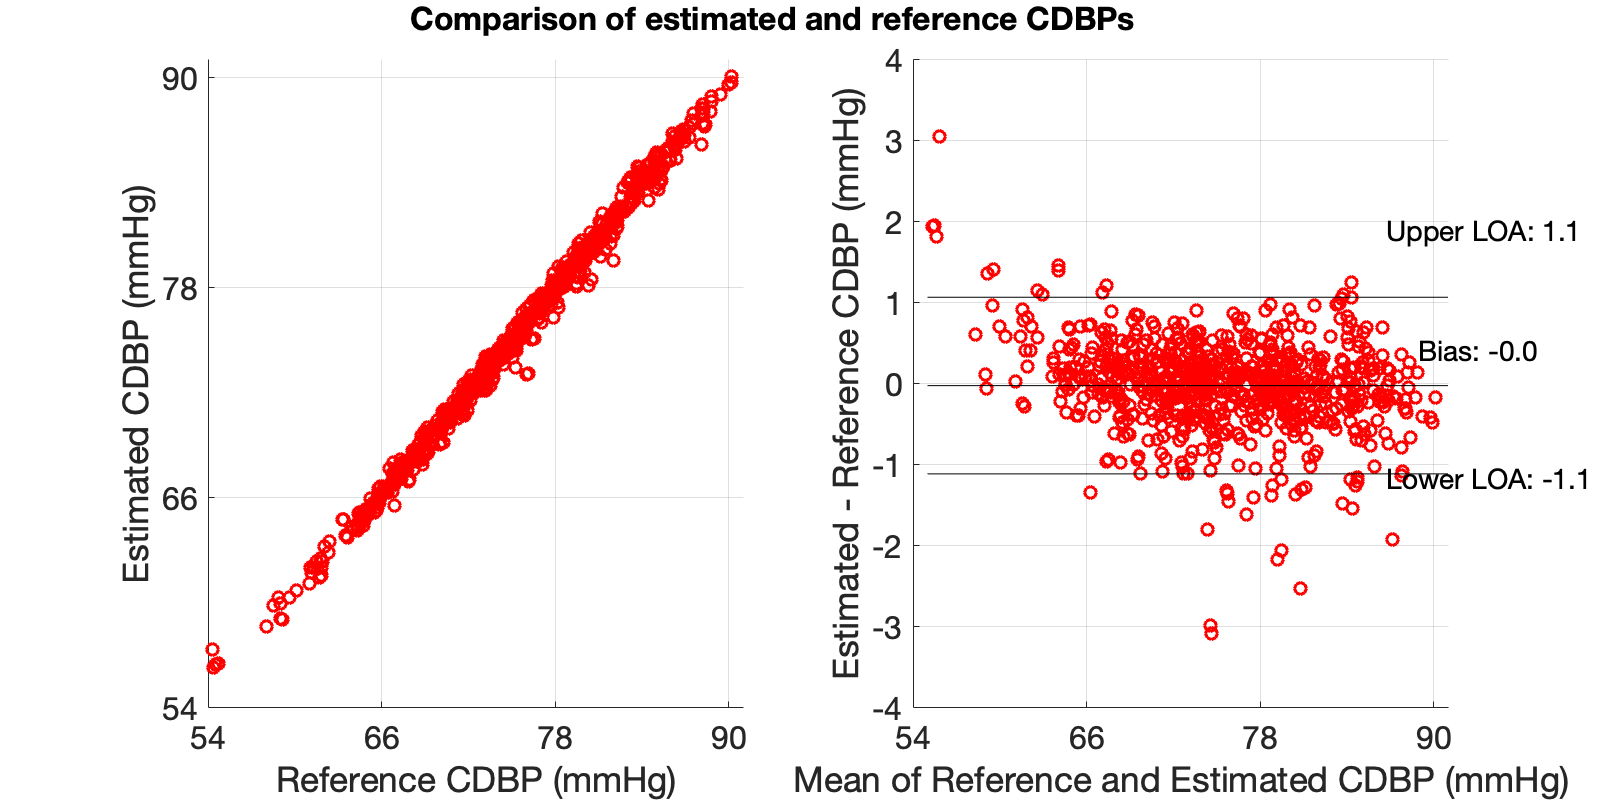

% plot options
figure('Position', [20, 20, 800, 400])

% Scatter Plot
subplot(1,2,1)
lwidth = 1.5; ftsize = 16;
plot(y_test_cdbp, y_pred_cdbp, 'or', 'LineWidth', lwidth)
xlabel('Reference CDBP (mmHg)', 'FontSize', ftsize)
ylabel('Estimated CDBP (mmHg)', 'FontSize', ftsize)
grid on
lims = [floor(min([y_test_cdbp; y_pred_cdbp])), ceil(max([y_test_cdbp; y_pred_cdbp]))];
xlim(lims), ylim(lims)
set(gca, 'XTick', lims(1):12:lims(2), 'YTick', lims(1):12:lims(2))
set(gca, 'FontSize', ftsize), box off


% Bland-Altman plot
subplot(1,2,2)
errors = y_pred_cdbp-y_test_cdbp;
plot(mean([y_test_cdbp, y_pred_cdbp],2), errors, 'or', 'LineWidth', lwidth), hold on
% - bias
bias = mean(errors);
plot(xlim, bias*ones(1,2), 'k')
dim = [.88 .49 .1 .1];
str = sprintf('Bias: %.1f', bias);
annotation('textbox',dim,'String',str,'LineStyle','none','FontSize', ftsize - 2);
% - upper loa
upper_loa = bias + 1.96*std(errors);
plot(xlim, upper_loa*ones(1,2), 'k')
dim = [.86 .64 .1 .1];
str = sprintf('Upper LOA: %.1f', upper_loa);
annotation('textbox',dim,'String',str,'LineStyle','none','FontSize', ftsize - 2);
% - lower loa
lower_loa = bias - 1.96*std(errors);
plot(xlim, lower_loa*ones(1,2), 'k')
dim = [.86 .33 .1 .1];
str = sprintf('Lower LOA: %.1f', lower_loa);
annotation('textbox',dim,'String',str,'LineStyle','none','FontSize', ftsize - 2);
% - tidy up plot
xlabel('Mean of Reference and Estimated CDBP (mmHg)', 'FontSize', ftsize)
ylabel('Estimated - Reference CDBP (mmHg)', 'FontSize', ftsize)
ylimit = ceil(max(abs(errors)));
xlim(lims), ylim([-ylimit,ylimit])
set(gca, 'FontSize', ftsize, 'XTick', lims(1):12:lims(2)), box off, grid on
set(gca, 'FontSize', ftsize, 'YTick', -ylimit:1:ylimit), box off, grid on

% title
dim = [.25 .91 .1 .1];
str = 'Comparison of estimated and reference CDBPs';
annotation('textbox',dim,'String',str,'LineStyle','none','FontSize', ftsize,'fontweight','bold');

A minimal bias was reported for the estimated CDBP. The LoAs between the estimated and reference CDBP were found to be equal to ±1 mmHg.

**Step 7: Perform external validation for the trained model**

Assess the model's performance on the hold-out validation set.

% calculate model estimates for CSBP (using Matlab function)
y_pred_ext_csbp = predict(func_csbp, X_val);
% calculate model estimates for CDBP (using Matlab function)
y_pred_ext_cdbp = predict(func_cdbp, X_val);

Plot the results as scatter plot of estimated against reference CSBP, and Bland-Altman plot showing the limits of agreement (LOAs) between the estimated and reference CSBP.

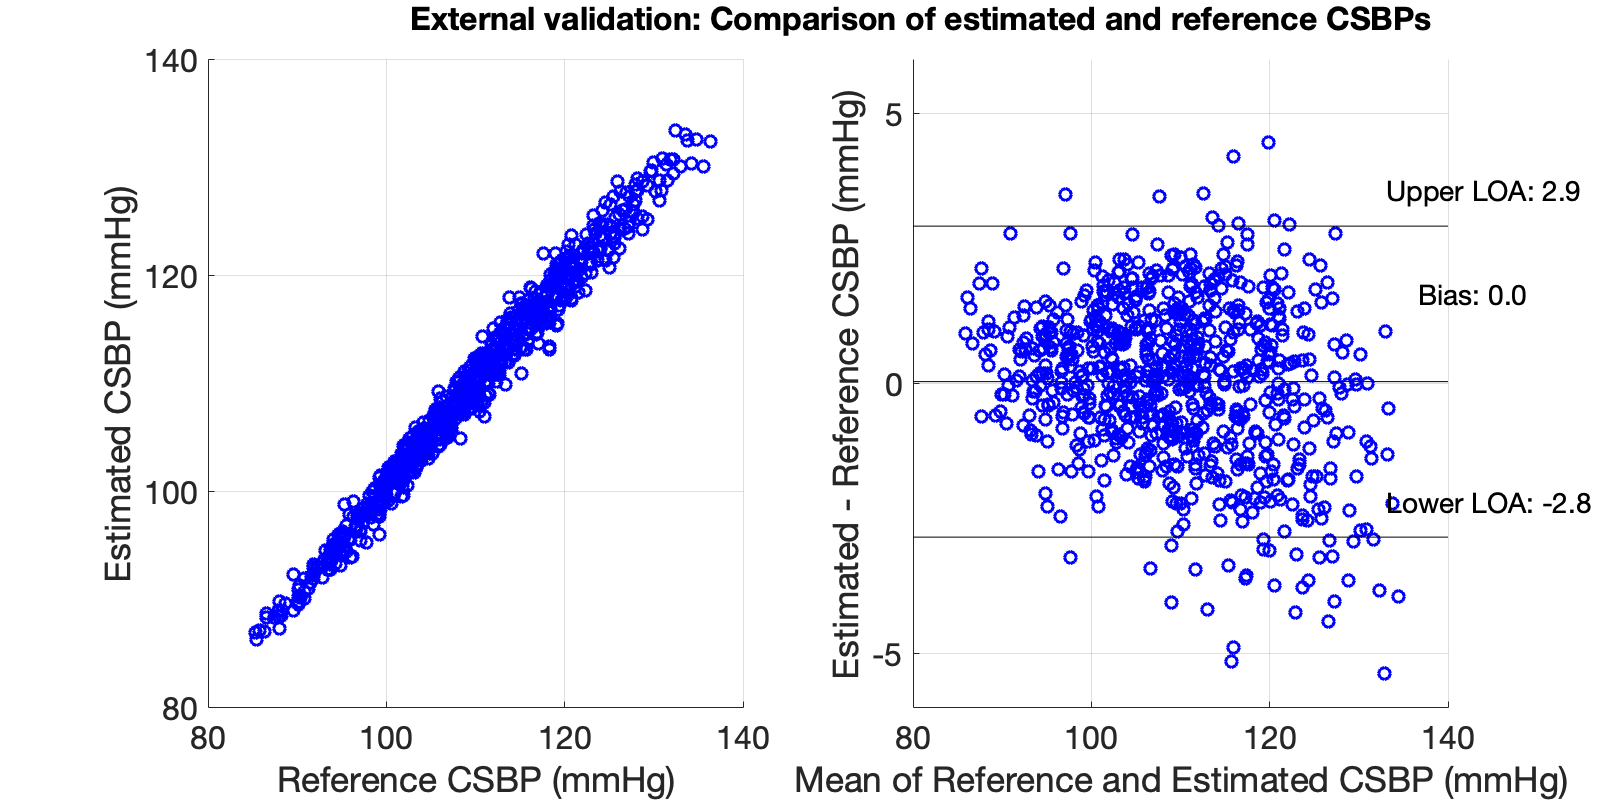

% plot options
figure('Position', [20, 20, 800, 400])

% Scatter Plot
subplot(1,2,1)
lwidth = 1.5; ftsize = 16;
plot(y_val_csbp, y_pred_ext_csbp, 'ob', 'LineWidth', lwidth)
xlabel('Reference CSBP (mmHg)', 'FontSize', ftsize)
ylabel('Estimated CSBP (mmHg)', 'FontSize', ftsize)
grid on
% lims = [floor(min([y_test_csbp; y_pred_csbp])), ceil(max([y_test_csbp; y_pred_csbp]))];
% xlim(lims), ylim(lims)
set(gca, 'XTick', 80:20:140, 'YTick', 80:20:140)
set(gca, 'FontSize', ftsize), box off

% Bland-Altman plot
subplot(1,2,2)
errors = y_pred_ext_csbp-y_val_csbp;
plot(mean([y_val_csbp, y_pred_ext_csbp],2), errors, 'ob', 'LineWidth', lwidth), hold on
% - bias
bias = mean(errors);
plot(xlim, bias*ones(1,2), 'k')
dim = [.88 .56 .1 .1];
str = sprintf('Bias: %.1f', bias);
annotation('textbox',dim,'String',str,'LineStyle','none','FontSize', ftsize - 2);
% - upper loa
upper_loa = bias + 1.96*std(errors);
plot(xlim, upper_loa*ones(1,2), 'k')
dim = [.86 .69 .1 .1];
str = sprintf('Upper LOA: %.1f', upper_loa);
annotation('textbox',dim,'String',str,'LineStyle','none','FontSize', ftsize - 2);
% - lower loa
lower_loa = bias - 1.96*std(errors);
plot(xlim, lower_loa*ones(1,2), 'k')
dim = [.86 .3 .1 .1];
str = sprintf('Lower LOA: %.1f', lower_loa);
annotation('textbox',dim,'String',str,'LineStyle','none','FontSize', ftsize - 2);
% - tidy up plot
xlabel('Mean of Reference and Estimated CSBP (mmHg)', 'FontSize', ftsize)
ylabel('Estimated - Reference CSBP (mmHg)', 'FontSize', ftsize)
set(gca, 'FontSize', ftsize, 'XTick', 80:20:140), box off, grid on
set(gca, 'FontSize', ftsize, 'YTick', -15:5:15), box off, grid on

% title
dim = [.25 .91 .1 .1];
str = 'External validation: Comparison of estimated and reference CSBPs';
annotation('textbox',dim,'String',str,'LineStyle','none','FontSize', ftsize,'fontweight','bold');

The Bland-Altman plot shows that the estimated CSBP had low bias for the external validation. The LoAs between the estimated and reference CSBP (within which 95% of errors are expected to lie) were found to be ±3  mmHg.

Plot the results as scatter plot of estimated against reference CDBP, and Bland-Altman plot showing the LOAs between the estimated and reference CDBP.

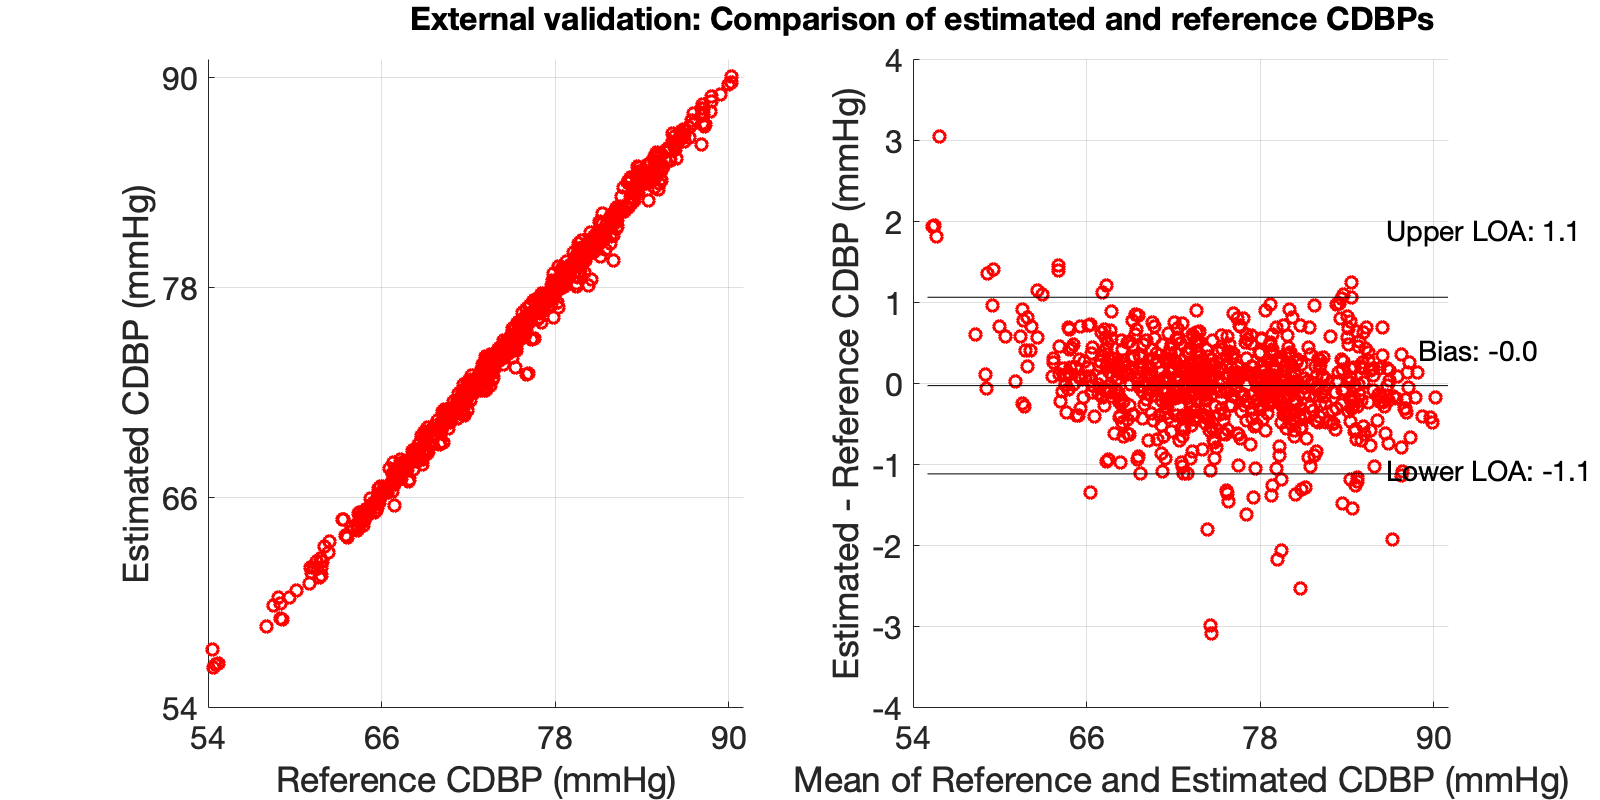

% plot options
figure('Position', [20, 20, 800, 400])

% Scatter Plot
subplot(1,2,1)
lwidth = 1.5; ftsize = 16;
plot(y_test_cdbp, y_pred_cdbp, 'or', 'LineWidth', lwidth)
xlabel('Reference CDBP (mmHg)', 'FontSize', ftsize)
ylabel('Estimated CDBP (mmHg)', 'FontSize', ftsize)
grid on
lims = [floor(min([y_test_cdbp; y_pred_cdbp])), ceil(max([y_test_cdbp; y_pred_cdbp]))];
xlim(lims), ylim(lims)
set(gca, 'XTick', lims(1):12:lims(2), 'YTick', lims(1):12:lims(2))
set(gca, 'FontSize', ftsize), box off


% Bland-Altman plot
subplot(1,2,2)
errors = y_pred_cdbp-y_test_cdbp;
plot(mean([y_test_cdbp, y_pred_cdbp],2), errors, 'or', 'LineWidth', lwidth), hold on
% - bias
bias = mean(errors);
plot(xlim, bias*ones(1,2), 'k')
dim = [.88 .49 .1 .1];
str = sprintf('Bias: %.1f', bias);
annotation('textbox',dim,'String',str,'LineStyle','none','FontSize', ftsize - 2);
% - upper loa
upper_loa = bias + 1.96*std(errors);
plot(xlim, upper_loa*ones(1,2), 'k')
dim = [.86 .64 .1 .1];
str = sprintf('Upper LOA: %.1f', upper_loa);
annotation('textbox',dim,'String',str,'LineStyle','none','FontSize', ftsize - 2);
% - lower loa
lower_loa = bias - 1.96*std(errors);
plot(xlim, lower_loa*ones(1,2), 'k')
dim = [.86 .34 .1 .1];
str = sprintf('Lower LOA: %.1f', lower_loa);
annotation('textbox',dim,'String',str,'LineStyle','none','FontSize', ftsize - 2);
% - tidy up plot
xlabel('Mean of Reference and Estimated CDBP (mmHg)', 'FontSize', ftsize)
ylabel('Estimated - Reference CDBP (mmHg)', 'FontSize', ftsize)
ylimit = ceil(max(abs(errors)));
xlim(lims), ylim([-ylimit,ylimit])
set(gca, 'FontSize', ftsize, 'XTick', lims(1):12:lims(2)), box off, grid on
set(gca, 'FontSize', ftsize, 'YTick', -ylimit:1:ylimit), box off, grid on

% title
dim = [.25 .91 .1 .1];
str = 'External validation: Comparison of estimated and reference CDBPs';
annotation('textbox',dim,'String',str,'LineStyle','none','FontSize', ftsize,'fontweight','bold');

A minimal bias was reported for the estimated CDBP. The LoAs between the estimated and reference CDBP were found to be close to ±1 mmHg.

*Version: 0.1 (2nd June 2020)*

*Copyright: Vasiliki Bikia (vasiliki.bikia@epfl.ch), Swiss Federal Institure of Technology, Lausanne 2020*

*Licence: Available under the GNU public license - please see the accompanying file named "LICENSE"*